data = csvread('data.csv', 1, 0);

ls = LeastSquare;
ls.A = data(:,1);
ls.b = data(:,2);
resultVector = ls.solveLeastSquare(10);

start least square
Elapsed time is 0.000930 seconds.
Elapsed time is 0.001416 seconds.


ans =   handle to deleted FunctionLine


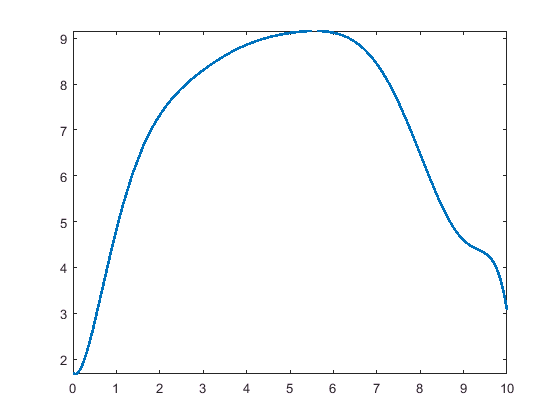

flipVector = flipud(resultVector);
polynom = poly2sym(flipVector);

G = GraphLogScale;
G.x = data(:,1);
G.y = data(:,2);
G.p = polynom;
G.f_plot(0, 10)

ans =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.500000000000000
              XData: [0 0.500000000000000 1 1.500000000000000 2 2.500000000000000 3 3.500000000000000 4 4.500000000000000 5 5.500000000000000 6 6.500000000000000 7 7.500000000000000 8 8.500000000000000 9 9.500000000000000 10]
              YData: [1x21 double]
              ZData: [1x0 double]
              CData: [0 0.447000000000000 0.741000000000000]

  Show all properties


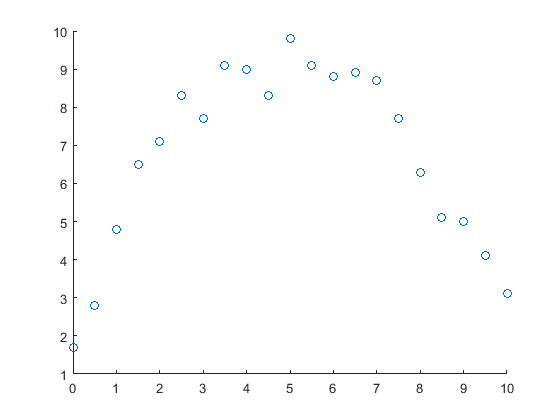

G.scater_plot